# Assessing network properties at different levels of another network property

For example, are there group differences in power, for nodes with low amounts of centrality, or high amounts of centrality, or both?

# First retreive Master Data Set

close all force
cog_task_list = {'PVT'};
df_long =  dflong('cogtestlist',cog_task_list,'getd2cdf',false);


Getting GPSD during PVT Task. . . . . . . . . . . . -done

Getting Network Props during PVT: . . . . . . . . . . . . -done


# **CHOOSE WHAT TO ANALYZE**

clearvars -except df_long
clc;

% SETTINGS
cogtask = 'PVT';
t=1;

bandname  = 'alpha';
ntwprop_X = 'deg_w'; 
ntwprop_Y = 'gpsd'; 
numlevels = 3;
bonfcorrect = 2;

testtype = 'signrank';
printSummResults = 'true';
printAllResults = 'off';
categ_method.subjects = true;
categ_method.condition = true;



## INITIATE STUFF

% INIT OTHER STUFF
ntwprop_X_level  = sprintf('%s_level',ntwprop_X);
ntwprop_Y_mean =  sprintf('mean_%s',ntwprop_Y);
printline = @() fprintf(' \n_________________________________________________________________________');

if  categ_method.subjects == true && categ_method.condition == true
    catmethod_str = 'WITHIN a subject AND within a condition';
elseif  categ_method.subjects == true && categ_method.condition == false
    catmethod_str = 'WITHIN a subject only, but ACCROSS conditions';
elseif categ_method.subjects == false && categ_method.condition == true
    catmethod_str = 'WITHIN a conditions only, but ACCROSS subjects';
elseif categ_method.subjects == false && categ_method.condition == false
    catmethod_str = 'ACCROSS all subjects and ACCROSS ALL CONDITIONS';    
else
    error('luis check above')
end

% INIT FIG
close all force
figure('Visible','on','GraphicsSmoothing','off');


T = tiledlayout('flow');
T.Title.HorizontalAlignment = 'center';
T.Title.FontWeight = 'bold';

#  PLOT DV, CONDITIONAL ON THE LEVEL OF THE IV, BUT AFTER AVERAGING CHANNELS **WITHIN A SUBJECT**

% GET DATA

df          = dflong2wide(df_long, cogtask, {'baseline', 'control','light'}, bandname, t, 'grouping_vars',[],'keepchannels',true);
df          = categcolumn(df,ntwprop_X,numlevels,"condition",categ_method.condition, "subject",categ_method.condition);
df_mean = groupsummary(df, ["condition", ntwprop_X_level,"sbj"],{"mean"},{ntwprop_Y});



% TEST

clear tests
sig_pairs_lev_mean = {};
for level = 1:numlevels
    df_mean_lev = df_mean(df_mean.(ntwprop_X_level) == sprintf('%d',level),:);
    [~,~,tests(level)] = runmultitests(df_mean_lev,ntwprop_Y_mean,'printSummResults',printSummResults,'printAllResults',printAllResults);
    sig_pairs_lev_mean = cat(2,getsigpairs(tests(level), level,'testtype',testtype,'bonfcorrect',bonfcorrect),sig_pairs_lev_mean);
end



 PLOT  

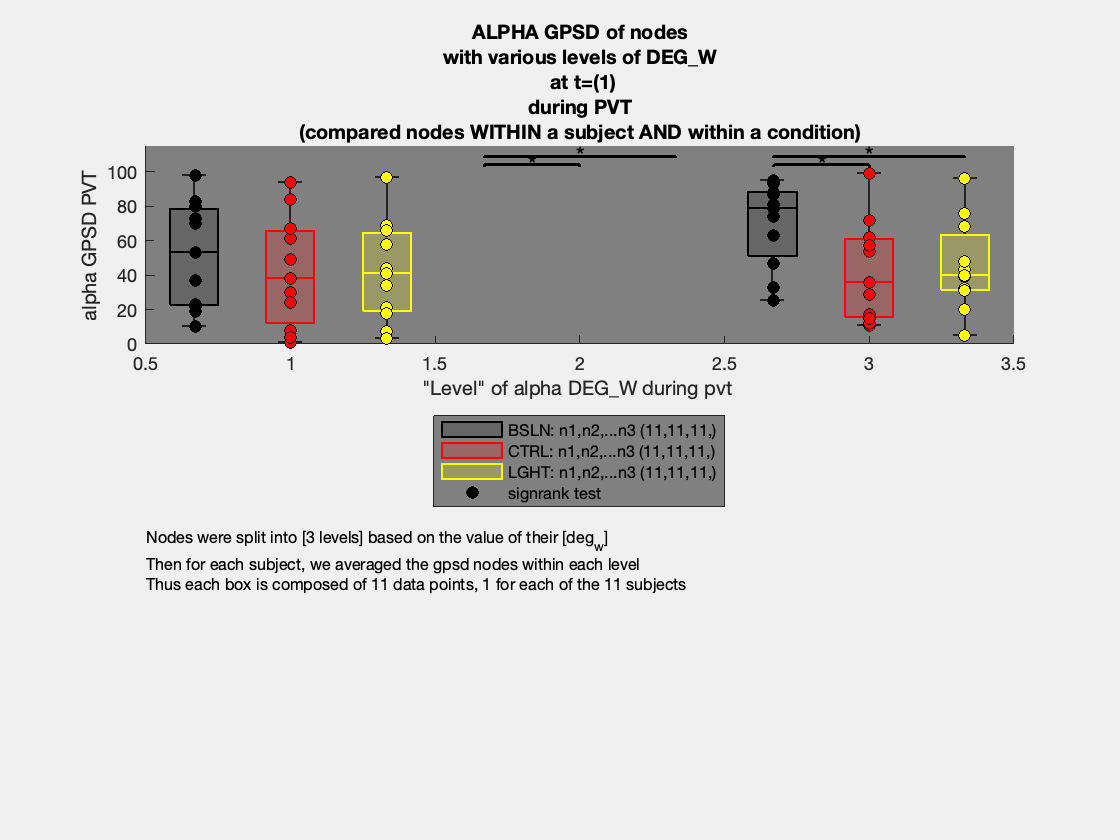

% ACCROSS SUBJECTS
df_mean.(ntwprop_Y_mean) = findgroups(df_mean.(ntwprop_Y_mean));
df_mean.(ntwprop_X_level) = findgroups(df_mean.(ntwprop_X_level));

ax_within = nexttile; hold on
ax_within.Color = [.5 .5 .5];
ax_bx = boxchart(df_mean.(ntwprop_X_level),df_mean.(ntwprop_Y_mean),'GroupByColor',df_mean.condition,'Notch','off');
ax_bx(1).BoxFaceColor = 'k';
ax_bx(2).BoxFaceColor = 'r';
ax_bx(3).BoxFaceColor = 'y';

ax_bx(1).YData(~ismember(ax_bx(1).XData,[1 numlevels])) = nan;    
ax_bx(2).YData(~ismember(ax_bx(2).XData,[1 numlevels])) = nan;    
ax_bx(3).YData(~ismember(ax_bx(3).XData,[1 numlevels])) = nan;    


% PLOT MEANS FROM EACH SUBJECT
sbjid_list = unique(df.sbj);
markkeroffset = [-.33 0 .33];

condition_list = {'baseline','control','light'};
color_list = ["k","r","y"];

for i = 1:3
    df_cnd= df_mean(df_mean.condition == condition_list(i),:);
    df_cnd.(ntwprop_X_level) = findgroups(df_cnd.(ntwprop_X_level));
    x =  df_cnd.(ntwprop_X_level)+ markkeroffset(i); 
    y = df_cnd.(ntwprop_Y_mean);
    ax_scatt = scatter(x,y,color_list(i),'filled','MarkerEdgeColor','k'); 
    
    ax_scatt.YData(~ismember(df_cnd.(ntwprop_X_level),[1 numlevels])) = nan;    
   
end
sigstar(sig_pairs_lev_mean);
ylabel(sprintf('%s %s %s',bandname, upper(ntwprop_Y), cogtask),'Interpreter','none')
xlabel(sprintf('"Level" of %s %s during %s ',bandname, upper(ntwprop_X),lower(cogtask)),'Interpreter','none')

bl_str = strcat( sprintf('BSLN: n1,n2,...n%d (',numlevels), sprintf('%d,', groupcounts(ax_bx(1).XData)) ,')');
ctrl_str = strcat( sprintf('CTRL: n1,n2,...n%d (',numlevels), sprintf('%d,', groupcounts(ax_bx(2).XData)) ,')');
light_str = strcat( sprintf('LGHT: n1,n2,...n%d (',numlevels), sprintf('%d,', groupcounts(ax_bx(3).XData)) ,')');


title(sprintf('%s %s of nodes\nwith various levels of %s\n at t=(%s)\n during %s \n(compared nodes %s)',upper(bandname), ...
    upper(ntwprop_Y), upper(ntwprop_X),num2str(t),cogtask,catmethod_str),'Interpreter','none');
if ~isempty(sig_pairs_lev_mean)
    legend({bl_str,ctrl_str,light_str,sprintf('%s test',testtype)},'Location','southoutside','Interpreter','none')
else
    legend({bl_str,ctrl_str,light_str},'Location','southoutside','Interpreter','none')

end

% PLOT INFO
info_str = strcat( ...
    sprintf('\nNodes were split into [%d levels] based on the value of their [%s]\n', numlevels,ntwprop_X),...
    sprintf('\nThen for each subject, we averaged the %s nodes within each level',ntwprop_Y),...
    sprintf('\nThus each box is composed of %d data points, 1 for each of the %d subjects',numel(sbjid_list),numel(sbjid_list))...
    );


nexttile; axis off


text(0,1,info_str,'FontSize',8)

# OR PLOT VALUE OF NETWORK PROPERTY, FOR EACH LEVEL OF THE X NETWORK PROPERTY **!WITH ALL CHANNELS!**

## **Get data **

df          = dflong2wide(df_long, cogtask, {'baseline', 'control','light'}, bandname, t, 'grouping_vars',[],'keepchannels',true);
df          = categcolumn(df,ntwprop_X,numlevels,"condition",categ_method.condition, "subject",categ_method.condition);
figure('Visible','on','GraphicsSmoothing','off');


INIT FIG

T = tiledlayout(2,2);
T.Title.HorizontalAlignment = 'right';
T.Title.FontWeight = 'bold';
T.Title.String = sprintf('%s %s of nodes\nwith various levels of %s\n at t=(%s)\n during %s \n(compared nodes %s)',upper(bandname), ...
    upper(ntwprop_Y), upper(ntwprop_X),num2str(t),cogtask,catmethod_str);
T.Title.FontSize = T.Title.FontSize ;

## TEST

clear tests
sig_pairs_lev = {};
for level = 1:numlevels
    df_lev = df(df.(ntwprop_X_level) == sprintf('%d',level),:);
    [~,~,tests(level)] = runmultitests(df_lev,ntwprop_Y,'printSummResults',printSummResults,'printAllResults',printAllResults);
    sig_pairs_lev = cat(2,getsigpairs(tests(level), level,'testtype',testtype,'bonfcorrect',bonfcorrect),sig_pairs_lev);
end


##  PLOT

ax_conditional = nexttile;
plotcond(ax_conditional,df, ntwprop_X_level,ntwprop_Y,sig_pairs_lev,level,testtype);

info_str = strcat( ...
    sprintf('Nodes were split into [%d levels] based on the value of their [%s]', numlevels,ntwprop_X),...    
    sprintf('\nAll data points correspond to value of all channels of ALL subject\n')...
    );

% INFO
nexttile; axis off
text(-.3,.5,info_str,'FontSize',8)

# Or... PLOT ORIGINAL FIGURE 1 PLOTS OF THE DV, **BUT WITH ALL CHANNELS**

## **Get data**

df          = dflong2wide(df_long, cogtask, {'baseline', 'control','light'}, bandname, t, 'grouping_vars',[],'keepchannels',true);
df          = categcolumn(df,ntwprop_X,numlevels,"condition",categ_method.condition, "subject",categ_method.condition);
df_wide_sbj = dflong2wide(df_long, cogtask, {'baseline', 'control','light'}, bandname, t, 'grouping_vars',{'cogtest','condition','band_ord','run','sbj'},'keepchannels',true);
df_wide_sbj = categcolumn(df_wide_sbj,ntwprop_X,numlevels,"condition",categ_method.condition, "subject",categ_method.condition);

## TEST

[~,~,tests] = runmultitests(df, ntwprop_Y, 'printSummResults',printSummResults,'printAllResults',printAllResults);
sig_pairs = getsigpairs(tests, 'all','testtype',testtype,'bonfcorrect',bonfcorrect);


## PLOT (SEE FUNCTION)

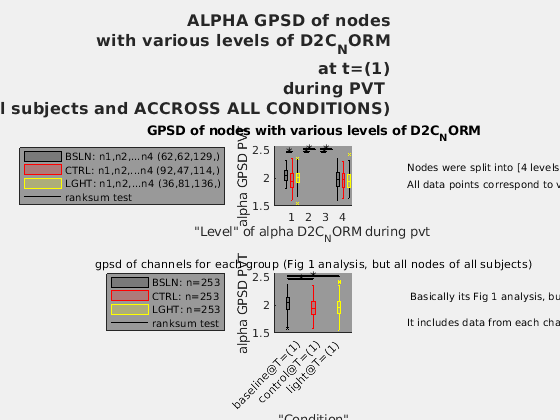

ax_avex =  nexttile;
plotuncond(ax_avex, df,ntwprop_Y,t,testtype,sig_pairs);

info_str = strcat...
    (...sprintf('\nPlot shows [%s] of each and every channel during each condition\n',upper(ntwprop_Y)),...
    sprintf('\n Basically its Fig 1 analysis, but not a global analysis.\n\nIt includes data from each channel\n')...
    );

% INFO
nexttile; axis off
text(-.3,.5,info_str,'FontSize',8)

# F(X) | F(X) |F(X) |F(X) |F(X) |F(X) |F(X) |F(X) |F(X) |F(X) |F(X) |F(X) |F(X) |

# F(X): ORIGINAL FIGURE 1 PLOTS OF THE DV, AVERAGING ACCROSS CHANNELS 

function plotuncond(ax_avex, df_wide,ntwprop_Y,t,testtype,sig_pairs)
    outliermarksize = 4;
    dx = .33;
    ax_bkgd_color = [.5 .5 .5];

    set(ax_avex,'Color',ax_bkgd_color,'NextPlot', 'add')
    
    
    % Make box chart of all data points
    ax_bx = boxchart(ax_avex,grp2idx(df_wide.condition),df_wide.(ntwprop_Y),'GroupByColor',df_wide.condition,'MarkerSize',outliermarksize,'MarkerStyle','x');
    set(ax_bx(1),'BoxFaceColor', 'k','WhiskerLineColor', 'k','MarkerColor', 'k')
    set(ax_bx(2),'BoxFaceColor', 'r','WhiskerLineColor', 'r','MarkerColor', 'r')
    set(ax_bx(3),'BoxFaceColor', 'y','WhiskerLineColor', 'y','MarkerColor', 'y')

    % plot significance bars
    sigstar(sig_pairs)
    
    % Clean up
    cogtask = cellstr(unique(df_wide.cogtest));
    bandname = cellstr(unique(df_wide.band_ord));    
    cond_set_str = strcat({'baseline', 'control','light'},{sprintf('@T=(%s)',num2str(t))});
    set(ax_avex,'Color',[.6 .6 .6],'XTick',[1 2 3],'XTickLabel',cond_set_str);
    ylabel(sprintf('%s %s %s',bandname{:}, upper(ntwprop_Y), cogtask{:}))
    xlabel('"Condition"')
    title(sprintf('%s of channels for each group (Fig 1 analysis, but all nodes of all subjects)',ntwprop_Y),'FontSize',9,'FontWeight','normal');

    bl_str = sprintf('BSLN: n=%d',groupcounts(ax_bx(1).XData));
    ctrl_str = sprintf('CTRL: n=%d',groupcounts(ax_bx(2).XData));
    light_str = sprintf('LGHT: n=%d',groupcounts(ax_bx(3).XData));    
    legend({bl_str,ctrl_str,light_str,sprintf('%s test',testtype)},'Location','westoutside')
end

# F(X)

function plotcond(ax_conditional,df_wide, ntwprop_X_level,ntwprop_Y,sig_pairs_lev,max_lev,testtype)
    outliermarksize = 4;

    boxwidth = .5;
    ax_bkgd_color = [.5 .5 .5];

    set(ax_conditional,'Color',ax_bkgd_color,'NextPlot', 'add')
    

    % Make box chart of all data points
    ax_bx = boxchart(ax_conditional, grp2idx(df_wide.(ntwprop_X_level)),df_wide.(ntwprop_Y), 'GroupByColor',df_wide.condition,'MarkerSize',outliermarksize,'BoxWidth',boxwidth,'MarkerStyle','x');
    set(ax_bx(1),'BoxFaceColor', 'k','WhiskerLineColor', 'k','MarkerColor', 'k')
    set(ax_bx(2),'BoxFaceColor', 'r','WhiskerLineColor', 'r','MarkerColor', 'r')
    set(ax_bx(3),'BoxFaceColor', 'y','WhiskerLineColor', 'k','MarkerColor', 'y')

    % show extremes only
    ax_bx(1).YData(~ismember(ax_bx(1).XData,[1 max_lev])) = nan;    
    ax_bx(2).YData(~ismember(ax_bx(2).XData,[1 max_lev])) = nan;    
    ax_bx(3).YData(~ismember(ax_bx(3).XData,[1 max_lev])) = nan;    


    ax_bx(1).XData(~ismember(ax_bx(1).XData,[1 max_lev])) = nan;    
    ax_bx(2).XData(~ismember(ax_bx(2).XData,[1 max_lev])) = nan;    
    ax_bx(3).XData(~ismember(ax_bx(3).XData,[1 max_lev])) = nan;      
    % plot significance bars
    sigstar(sig_pairs_lev);

    
    % Clean up
    ntwprop_X = ntwprop_X_level(1:strfind(ntwprop_X_level,'_level')-1);
    cogtask = cellstr(unique(df_wide.cogtest));
    bandname = cellstr(unique(df_wide.band_ord));

    set(ax_conditional,'Color',[.6 .6 .6],'XTick',1:max_lev,'XTickLabel',1:max_lev);
    title(sprintf('%s of nodes with various levels of %s',upper(ntwprop_Y), upper(ntwprop_X)));
    ylabel(sprintf('%s %s %s',bandname{:}, upper(ntwprop_Y), cogtask{:}))
    xlabel(sprintf('"Level" of %s %s during %s ',bandname{:}, upper(ntwprop_X),lower(cogtask{:})));


    bl_str = strcat( sprintf('BSLN: n1,n2,...n%d (',max_lev), sprintf('%d,', groupcounts(ax_bx(1).XData)) ,')');
    ctrl_str = strcat( sprintf('CTRL: n1,n2,...n%d (',max_lev), sprintf('%d,', groupcounts(ax_bx(2).XData)) ,')');
    light_str = strcat( sprintf('LGHT: n1,n2,...n%d (',max_lev), sprintf('%d,', groupcounts(ax_bx(3).XData)) ,')');
    
    legend({bl_str,ctrl_str,light_str,sprintf('%s test',testtype)},'Location','westoutside')
    gs = groupsummary(df_wide, {ntwprop_X_level,'condition','band_ord','run'},{'mean','median','std','min','max','nummissing','nnz'},ntwprop_Y,"IncludeEmptyGroups",false);
%     disp(sortrows(gs,ntwprop_X_level));
end

# F(X): Make it easier to find group pairs that are significant from ttest

function sig_pairs = getsigpairs(test_results, lev,opts)
    arguments
        test_results, lev
        opts.testtype = 'ttest'
        opts.bonfcorrect = 1;

    end
    
    % set the locations of bar ends
    if ischar(lev)
        % For 'unconditional' plot 
        if strcmpi(lev,'all')
            bl_loc = .66;
            ctrl_loc = 2;
            light_loc = 3.33;
        end
    elseif isnumeric(lev) 
        % For plot where Y is conditional on X
        bl_loc = lev-.33;
        ctrl_loc = lev;
        light_loc = lev+.33;
    end

    
    switch opts.testtype
        case {'ttest','t'}
            ctrl_p = test_results.control.ttest_p;
            light_p = test_results.light.ttest_p;
        case {'signrank'}
            ctrl_p = test_results.control.ranktest_p;
            light_p = test_results.light.ranktest_p;            
        otherwise
            error('LUIS!!!!: unkown test type')
    end

    sig_pairs = {};    
    if ctrl_p<(.05/opts.bonfcorrect)
        sig_pairs = cat(2,sig_pairs,[bl_loc ctrl_loc]);
    end
    if light_p< (.05/opts.bonfcorrect)
        sig_pairs = cat(2,sig_pairs,[bl_loc light_loc]);
    end  


end


